clear all
clc
addpath('H:\GIT project\abzar dagig\')

ID = 810199492

ID = 810199492


x = 1:100

x =      1     2     3     4     5     6     7     8     9    10    11    12    13    14    15    16    17    18    19    20    21    22    23    24    25    26    27    28    29    30    31    32    33    34    35    36    37    38    39    40    41    42    43    44    45    46    47    48    49    50


for i = 1:100
    y(1,i) = sensor(x(i),ID);
end
display(y(1,1))

   23.0333




data = vertcat(x,y)

data = 	1.0e+10 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0003    0.0004    0.0006    0.0007    0.0009    0.0012    0.0014    0.0018    0.0022    0.0026    0.0032    0.0038    0.0046    0.0054    0.0064    0.0075    0.0087    0.0101    0.0117    0.0134    0.0154    0.0176    0.0200    0.0227    0.0257    0.0290    0.0326    0.0366    0.0409    0.0457    0.0508    0.0565

[trainingData, validationData, testData] = dividerand(data, 0.8, 0, 0.2);
x_train =trainingData(1,:)

x_train =      2     3     4     5     6     8     9    11    12    13    14    15    16    19    20    21    23    24    25    26    30    31    33    34    35    37    38    39    40    41    42    43    44    45    46    47    49    50    51    53    54    55    56    57    58    59    60    61    62    64


y_train =trainingData(2,:)

y_train = 	1.0e+10 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    0.0001    0.0001    0.0002    0.0002    0.0006    0.0007    0.0009    0.0014    0.0018    0.0022    0.0026    0.0054    0.0064    0.0087    0.0101    0.0117    0.0154    0.0176    0.0200    0.0227    0.0257    0.0290    0.0326    0.0366    0.0409    0.0457    0.0508    0.0626    0.0692    0.0764    0.0926    0.1017    0.1114    0.1219    0.1332    0.1453    0.1582    0.1721    0.1869    0.2027    0.2375


x_test =testData(1,:)

x_test =      1     7    10    17    18    22    27    28    29    32    36    48    52    63    65    78    83    84    95   100


y_test =testData(2,:)

y_test = 	1.0e+10 *

    0.0000    0.0000    0.0000    0.0003    0.0004    0.0012    0.0032    0.0038    0.0046    0.0075    0.0134    0.0565    0.0842    0.2195    0.2566    0.6380    0.8702    0.9238    1.7085    2.2076



x_train_scaled = (x_train - min(x_train)) / (max(x_train) - min(x_train));
y_train_scaled = (y_train - min(y_train)) / (max(y_train) - min(y_train));

x_test_scaled = (x_test - min(x_train)) / (max(x_train) - min(x_train));
y_test_scaled = (y_test - min(y_train)) / (max(y_train) - min(y_train));

degrees = 1:20;

train_error = zeros(size(degrees));
test_error = zeros(size(degrees));

for i = 1:numel(degrees)

    p = polyfit(x_train_scaled, y_train_scaled, degrees(i));
    
    y_train_pred = polyval(p, x_train_scaled);
  
    y_test_pred = polyval(p, x_test_scaled);
    

    train_error(i) = mean((y_train_scaled - y_train_pred).^2);
    test_error(i) = mean((y_test_scaled - y_test_pred).^2);
end

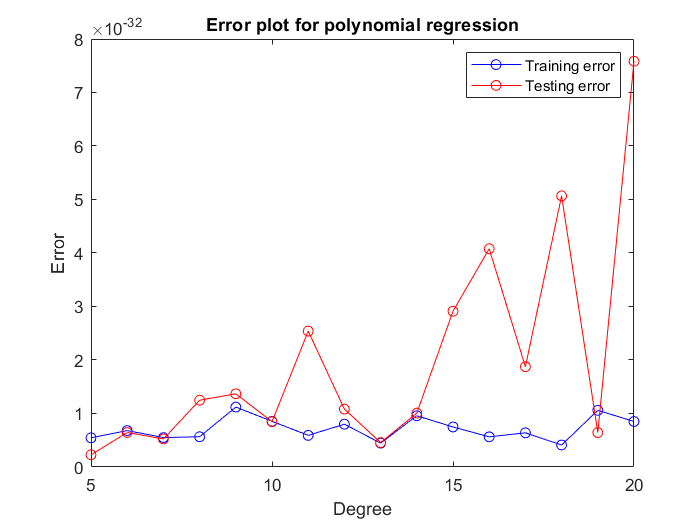


figure
plot(degrees(5:20), train_error(5:20), 'b-o', degrees(5:20), test_error(5:20), 'r-o')
legend('Training error', 'Testing error')
xlabel('Degree')
ylabel('Error')
title('Error plot for polynomial regression')

% LS
degree =6;

X = zeros(length(x), degree+1);
for i = 0:degree
    X(:,i+1) = x(:).^i;
end


coeffs = X \ y(:); 
display(coeffs)

coeffs =     3.0000
    7.2500
    9.3333
    0.5000
    0.7500
    2.2000
   -0.0000


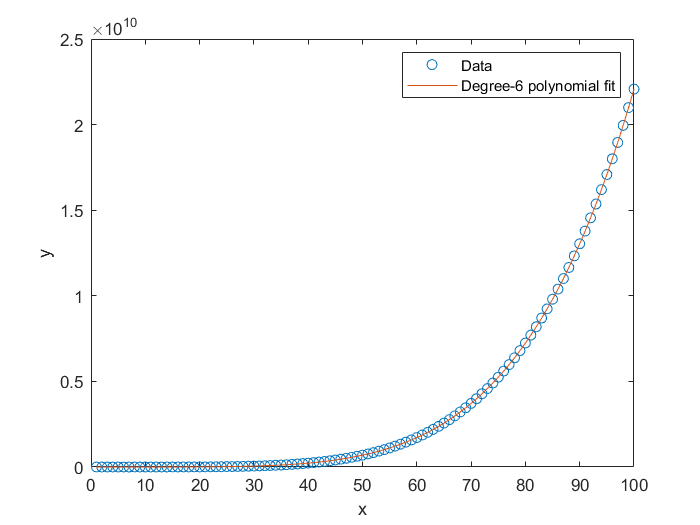


x_plot = linspace(min(x), max(x), 1000);
y_plot = zeros(size(x_plot));
for i = 0:degree
    y_plot = y_plot + coeffs(i+1)*x_plot.^i;
end
plot(x, y, 'o', x_plot, y_plot, '-');
legend('Data', 'Degree-6 polynomial fit');
xlabel('x');
ylabel('y');


%RLS
lambda = 1;
X = zeros(length(x), degree+1);
for i = 0:degree
    X(:,i+1) = x(:).^i; 
end


P = eye(degree+1)/lambda;
theta = zeros(degree+1, 1);
coeffs = zeros(degree+1, length(x));
traces = zeros(length(x), 1);

for t = 1:length(x)
    k = P * X(t,:)' / (lambda + X(t,:) * P * X(t,:)');
    P = 1/lambda * (P - k * X(t,:) * P);
    traces(t) = trace(P); % Store trace of P at this iteration
    
    e = y(t) - X(t,:) * theta;
    theta = theta + k * e;
    coeffs(:,t) = theta;
end

display(theta)

theta =     2.4511
    7.3224
    9.3300
    0.5001
    0.7500
    2.2000
   -0.0000



x_plot = linspace(min(x), max(x), 1000);
y_plot = zeros(size(x_plot));
for i = 0:degree
    y_plot = y_plot + coeffs(i+1,end)*x_plot.^i;
end
figure;
plot(x, y, 'o', x_plot, y_plot, '-');
legend('Data', 'Degree-6 polynomial fit');
xlabel('x');
ylabel('y');

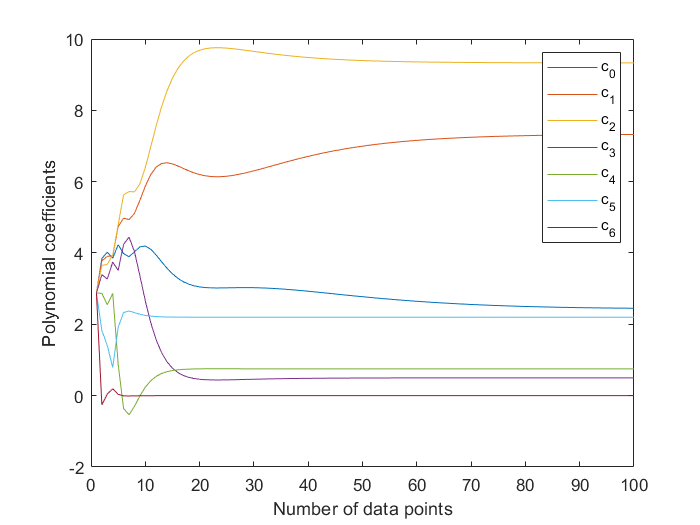


figure;
plot(1:length(x), coeffs');
xlabel('Number of data points');
ylabel('Polynomial coefficients');
legend('c_0', 'c_1', 'c_2', 'c_3', 'c_4', 'c_5', 'c_6');

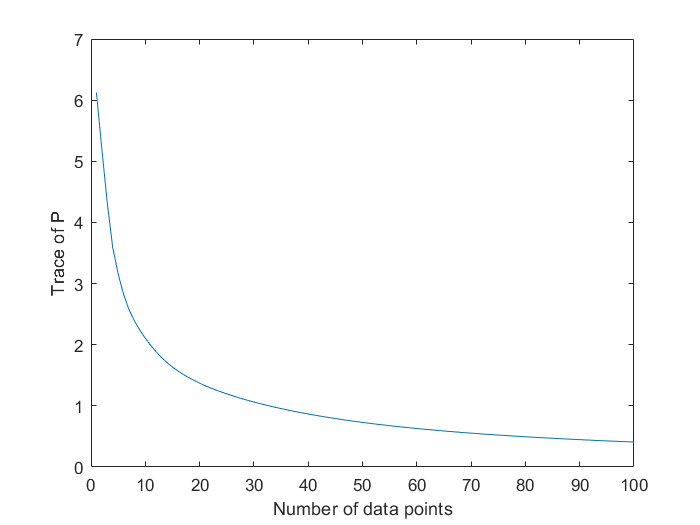


figure;
plot(1:length(x), traces);
xlabel('Number of data points');
ylabel('Trace of P');


%RLS
a=10^1;

lambda = 1;

X = zeros(length(x), degree+1);
for i = 0:degree
    X(:,i+1) = x(:).^i; 
end


P = eye(degree+1)/lambda*a;
theta = zeros(degree+1, 1);
coeffs = zeros(degree+1, length(x));
traces = zeros(length(x), 1);

for t = 1:length(x)
    k = P * X(t,:)' / (lambda + X(t,:) * P * X(t,:)');
    P = 1/lambda * (P - k * X(t,:) * P);
    traces(t) = trace(P); % Store trace of P at this iteration
    
    e = y(t) - X(t,:) * theta;
    theta = theta + k * e;
    coeffs(:,t) = theta;
end

display(theta)

theta =     2.9151
    7.2645
    9.3325
    0.5000
    0.7500
    2.2000
   -0.0000



x_plot = linspace(min(x), max(x), 1000);
y_plot = zeros(size(x_plot));
for i = 0:degree
    y_plot = y_plot + coeffs(i+1,end)*x_plot.^i;
end
figure;
plot(x, y, 'o', x_plot, y_plot, '-');
legend('Data', 'Degree-6 polynomial fit');
xlabel('x');
ylabel('y');

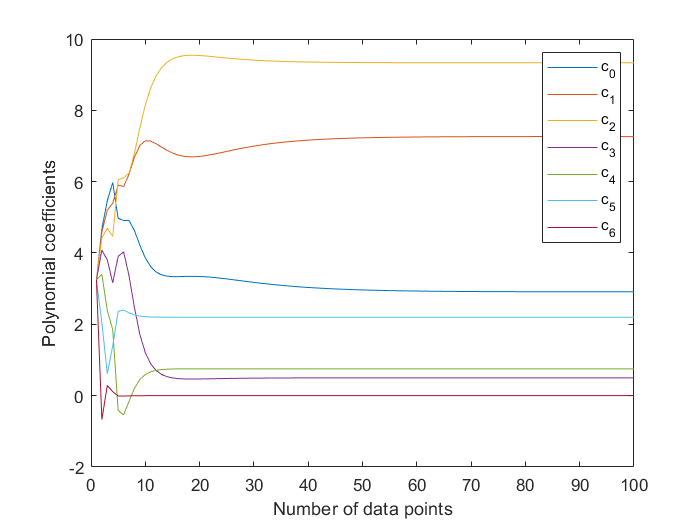


figure;
plot(1:length(x), coeffs');
xlabel('Number of data points');
ylabel('Polynomial coefficients');
legend('c_0', 'c_1', 'c_2', 'c_3', 'c_4', 'c_5', 'c_6');

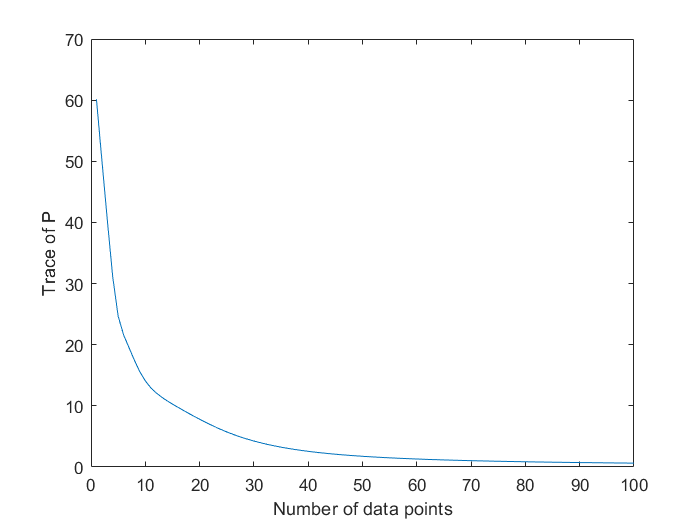


figure;
plot(1:length(x), traces);
xlabel('Number of data points');
ylabel('Trace of P');